close all;
clear all;
color.code=colormap(slanCM(160));

@author : slandarer


color.l=length(color.code);
color.index{1}=round(color.l/9);
color.index{2}=round(color.l*2.5/9);
color.index{3}=round(color.l*4/9);
color.index{4}=round(color.l*5.5/9);
color.index{5}=round(color.l*7/9);
color.index{6}=round(color.l*8.5/9);
L=15.5/2;
l1=3.025/2;
r1=5.12/2;
H=7/2;
l3=1.5/2;
r2=4.5/2;
phi=deg2rad(45);
E=17E6;
%E2=2E9;
b=2;
h=0.68;
Iz=b*h^3/12;
des=1.29e-3;
fct1=1;
fct2=1;
v=1/3;%%(mm/s)
dt=0.1;%%(s);
t=0:dt:24;
g=9800;%%(mm/s^2)
d=v*t;
lmd1=0.05:0.05:0.3

lmd1 =     0.0500    0.1000    0.1500    0.2000    0.2500    0.3000


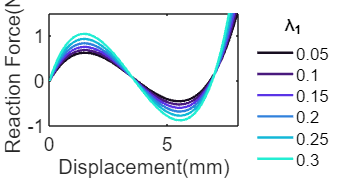

lmd3=0.05;
figure('DefaultAxesFontSize',17,'Position',[50 50 600 300])
%%K1
for q=1:length(lmd1)
    th0=solve_th0(L,lmd1(q),lmd3,H);
    K1=solve_k1(fct1,l1,L,lmd1(q),E,Iz);
    K2=solve_k2(fct2,L,E,Iz,K1,lmd1(q),lmd3,H);
    K3=solve_k3(K1,K2,E,b,h,th0,lmd1(q),lmd3,l1,l3,r1,r2,phi,H,L,Iz);
    [m2,m3]=calculate_mass(lmd1(q),lmd3,L,des,th0,b,h);
    l2=L*(1-lmd1(q)-lmd3)/cos(th0);
    th0=-th0;
    k1=3*K1;
    k2=3*K2;
    k3=1.5*K3;
    F1=lagrange_approach(d,H,v,th0,dt,k1,k2,k3,m2,m3,l2,g,L);
    plot(d,F1,'Color',color.code(color.index{q},:),'LineWidth',2);
    str{q}=[num2str(lmd1(q))];
    hold on
end
%title('k3/k2=',num2str(ratio)'');
lgd1=legend(str);
legend('boxoff');
legend('Location','northeastoutside','FontName','Arial');
xlabel('Displacement(mm)');
ylabel('Reaction Force(N)');
title(lgd1,'λ_1');
axis([0 8 -1 1.5]);


lmd1=0.05;
lmd3=0.05:0.05:0.3;
figure('DefaultAxesFontSize',17,'Position',[50 50 600 300])
%%K1
for q=1:length(lmd3)
    th0=solve_th0(L,lmd1,lmd3(q),H);
    K1=solve_k1(fct1,l1,E,Iz);
    K2=solve_k2(fct2,L,E,Iz,K1,lmd1,lmd3(q),H);
    K3=solve_k3(K1,E,b,h,th0,lmd1,lmd3(q),l1,l3,r1,r2,phi,H,L,Iz);
    [m2,m3]=calculate_mass(lmd1,lmd3(q),L,des,th0,b,h);
    l2=L*(1-lmd1-lmd3(q))/cos(th0);
    th0=-th0;
    k1=3*K1;
    k2=3*K2;
    k3=1.5*K3;
    F1=lagrange_approach(d,H,v,th0,dt,k1,k2,k3,m2,m3,l2,g,L);
    plot(d,F1,'Color',color.code(color.index{q},:),'LineWidth',2);
    str{q}=[num2str(lmd3(q))];
    hold on
end

Not enough input arguments.

Error in solve_k1 (line 2)
k1=c*E*Iz/(l1+lmd1*L);

%title('k3/k2=',num2str(ratio)'');
lgd1=legend(str);
legend('boxoff');
legend('Location','northeastoutside','FontName','Arial');
xlabel('Displacement(mm)');
ylabel('Reaction Force(N)');
title(lgd1,'λ_3');
axis([0 8 -1 1.5]);